# Daniel Chang

# M150 Lab 5

### **Exercise 1: **

### Complete the simulation code below for the spread of an infectious disease beginning with 1 individual out of 10000 and estimate the value of R0. And run the code. Do you expect the disease to spread or not? Then, change the value of p to 0.01 – will the disease spread, why or why not? (expecting two plots)

Based on my results below,

First Plot: Due to a p value of 0.025, R0 is greater than 1 (R0 = 2) meaning the disease will spread since each infectious person infects 2 new people on average. That being said, the outbreak infects a large fraction of the population.

Second Plot: Due to the p value changing to 0.01, R0 is less than 1 (R0 = 0.8) meaning each infectious person infects fewer than one new person on average. The disease dies out with spreading.  

#### First Plot: Estimating the value of R0 and p = 0.025

pars.c     = 20;
pars.p     = 0.025;
pars.beta  = pars.c * pars.p;     % = 0.5 days^-1
pars.gamma = 1/4;                  % = 0.25 days^-1
pars.R0    = pars.beta / pars.gamma; % = 2.0
pars.N     = 10000;
pars.I0    = 1;
pars.S0    = pars.N - pars.I0;
 
fprintf('Part A: beta=%.3f, R0=%.2f --> R0 > 1, disease WILL spread\n', ...
        pars.beta, pars.R0);

Part A: beta=0.500, R0=2.00 --> R0 > 1, disease WILL spread


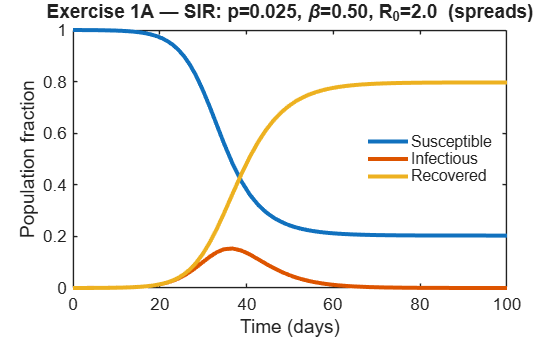

 
figure(1);
[t,y] = ode45(@(t,y) sir_model(t,y,pars), [0 100], [pars.S0 pars.I0 0]/pars.N);
tmph = plot(t, y);
set(tmph, 'linewidth', 3);
xlabel('Time (days)');
ylabel('Population fraction');
title(sprintf('Exercise 1A — SIR: p=%.3f, \\beta=%.2f, R_0=%.1f  (spreads)', ...
              pars.p, pars.beta, pars.R0));
tmplh = legend('Susceptible', 'Infectious', 'Recovered', 'Location', 'east');
legend('boxoff');
set(gca,'fontsize',13);
ylim([0 1]);

#### Second Plot: Changing the value of p to 0.01

pars.p     = 0.01;
pars.beta  = pars.c * pars.p;       % = 0.2 days^-1
pars.R0    = pars.beta / pars.gamma; % = 0.8
fprintf('Part B: beta=%.3f, R0=%.2f --> R0 < 1, disease will NOT spread\n', ...
    pars.beta, pars.R0);

Part B: beta=0.200, R0=0.80 --> R0 < 1, disease will NOT spread


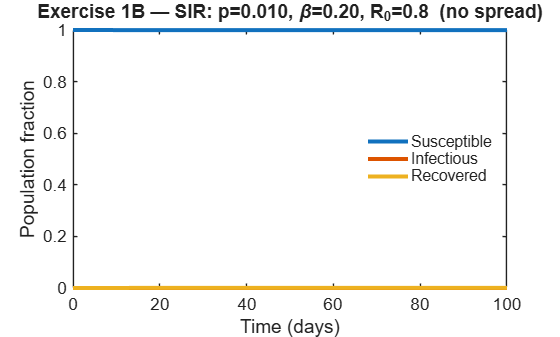


figure(2);
[t,y] = ode45(@(t,y) sir_model(t,y,pars), [0 100], [pars.S0 pars.I0 0]/pars.N);
tmph = plot(t, y);
set(tmph, 'linewidth', 3);
xlabel('Time (days)');
ylabel('Population fraction');
title(sprintf('Exercise 1B — SIR: p=%.3f, \\beta=%.2f, R_0=%.1f  (no spread)', ...
    pars.p, pars.beta, pars.R0));
tmplh = legend('Susceptible', 'Infectious', 'Recovered', 'Location', 'east');
legend('boxoff');
set(gca,'fontsize',13);
ylim([0 1]);

### **Exercises 2:** 

### Determine the strength and speed for the following sets of disease parameters.Calculate expected speed and then compare it with the estimated speed (estimated slope of log(I) versus time) and see if they match. Should create 4 plots (similar to the plot above) with corresponding transmission and recovery values.

According to my results below, in all four cases the estimated speed matches the theoretical value to within 1%, confirming the strength-speed relationship holds.

- beta=0.50, gamma=0.40, R0=1.25: 

**    r_theory = 0.100, r_estimated = 0.0998 **

- beta=1.00, gamma=0.50, R0=2.00:

   ** r_theory = 0.500, r_estimated = 0.4954**

- beta=0.25, gamma=0.50, R0=0.50:

     **r_theory = -0.250, r_estimated = -0.2500** 

- beta=0.75, gamma=0.25, R0=3.00:

     **r_theory = 0.500, r_estimated = 0.4974**

0.50   0.40   | 1.250  0.1000   | 0.0998    


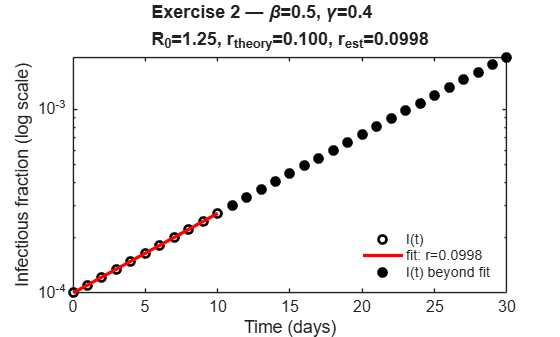

1.00   0.50   | 2.000  0.5000   | 0.4954    


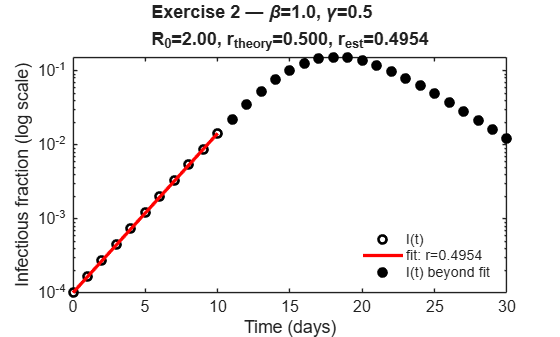

0.25   0.50   | 0.500  -0.2500  | -0.2500   


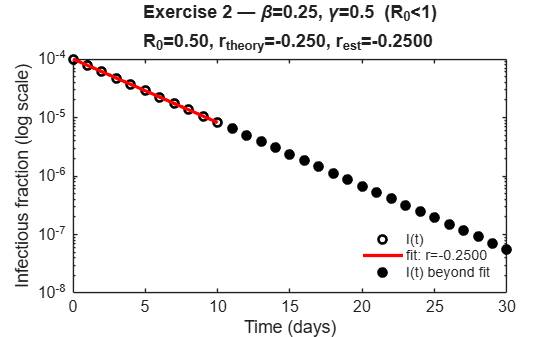

0.75   0.25   | 3.000  0.5000   | 0.4974    


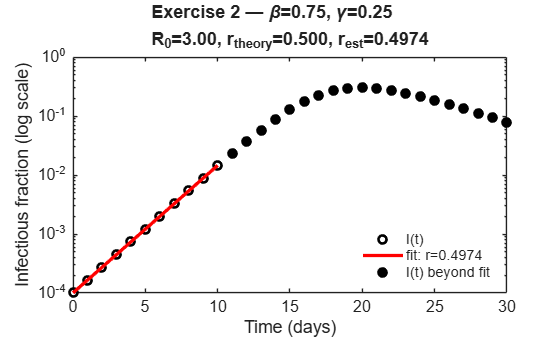

% R0 = beta / gamma
% r  = gamma*(R0 - 1) = beta - gamma
%
% Estimated r = slope of log(I) vs t during early (exponential) phase

pars.N  = 10000;
pars.I0 = 1;
pars.S0 = pars.N - pars.I0;

% Parameter sets [beta, gamma] according to the table to be tested
params = [0.5,  0.4;
          1.0,  0.5;
          0.25, 0.5;
          0.75, 0.25];

fig_titles = {'Exercise 2 — \beta=0.5, \gamma=0.4', ...
    'Exercise 2 — \beta=1.0, \gamma=0.5', ...
    'Exercise 2 — \beta=0.25, \gamma=0.5  (R_0<1)', ...
    'Exercise 2 — \beta=0.75, \gamma=0.25'};

for k = 1:4
    pars.beta  = params(k,1);
    pars.gamma = params(k,2);
    pars.R0    = pars.beta / pars.gamma;
    r_theory   = pars.gamma * (pars.R0 - 1);   % = beta - gamma

    % Simulate 10 days for the fit, 30 days for display
    [t10, y10] = ode45(@(t,y) sir_model(t,y,pars), 0:1:10, ...
        [pars.S0 pars.I0 0]/pars.N);
    [t30, y30] = ode45(@(t,y) sir_model(t,y,pars), 0:1:30, ...
        [pars.S0 pars.I0 0]/pars.N);

    % Fit line to log(I) vs t over first 10 days
    pfit        = polyfit(t10, log(y10(:,2)), 1);
    r_estimated = pfit(1);

    fprintf('%-6.2f %-6.2f | %-6.3f %-8.4f | %-10.4f\n', ...
        pars.beta, pars.gamma, pars.R0, r_theory, r_estimated);

    figure(2+k);
    % Open circles: exponential phase (0–10 days)
    semilogy(t10, y10(:,2), 'ko', 'linewidth', 2, 'markersize', 6);
    hold on;
    % Best-fit line (exponential)
    semilogy(t10, exp(pfit(1)*t10 + pfit(2)), 'r-', 'linewidth', 2.5);
    % Solid circles: beyond exponential phase
    tmpi = find(t30 > 10);
    semilogy(t30(tmpi), y30(tmpi,2), 'ko', 'linewidth', 2, ...
        'markerfacecolor', 'k', 'markersize', 6);
    xlabel('Time (days)'); ylabel('Infectious fraction (log scale)');
    title(sprintf('%s\nR_0=%.2f, r_{theory}=%.3f, r_{est}=%.4f', ...
        fig_titles{k}, pars.R0, r_theory, r_estimated));
    legend('I(t)', sprintf('fit: r=%.4f', r_estimated), 'I(t) beyond fit', ...
        'Location','southeast');
    legend('boxoff');
    set(gca,'fontsize',12);
    hold off;
end

### **Exercises 3:** 

### Given parameters β = 0.3 and γ = 0.25 days−1. Simulate and compare the results of SIR and SI model (should have two plots). For these parameters, simulate the dynamics over a 1 year = 365 day period

pars.beta  = 0.3;
pars.gamma = 0.25;    % days^-1
pars.R0    = pars.beta / pars.gamma;   % = 1.2
pars.N     = 10000;
pars.I0    = 1;
pars.S0    = pars.N - pars.I0;

S_star = 1 / pars.R0;
I_star = (pars.R0 - 1) / pars.R0;
fprintf('beta=%.2f, gamma=%.2f, R0=%.3f\n', pars.beta, pars.gamma, pars.R0);

beta=0.30, gamma=0.25, R0=1.200


fprintf('SI endemic equilibrium: S*=%.4f, I*=%.4f\n', S_star, I_star);

SI endemic equilibrium: S*=0.8333, I*=0.1667


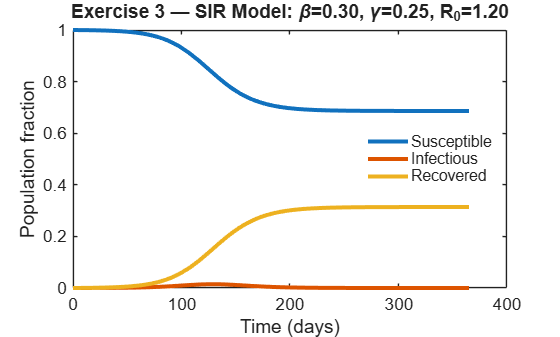


% SIR simulation
[t_sir, y_sir] = ode45(@(t,y) sir_model(t,y,pars), [0 365], ...
    [pars.S0 pars.I0 0]/pars.N);

figure(7);
tmph = plot(t_sir, y_sir);
set(tmph,'linewidth',3);
xlabel('Time (days)'); ylabel('Population fraction');
title(sprintf('Exercise 3 — SIR Model: \\beta=%.2f, \\gamma=%.2f, R_0=%.2f', ...
    pars.beta, pars.gamma, pars.R0));
legend('Susceptible','Infectious','Recovered','Location','east');
legend('boxoff');
set(gca,'fontsize',13);
ylim([0 1]);

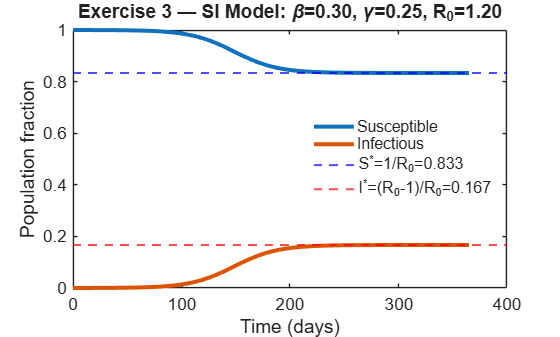


% SI simulation
[t_si, y_si] = ode45(@(t,y) si_model(t,y,pars), [0 365], ...
    [pars.S0 pars.I0]/pars.N);

figure(8);
tmph = plot(t_si, y_si);
set(tmph,'linewidth',3);
hold on;
% Mark endemic equilibrium lines
yline(S_star, 'b--', 'linewidth', 1.5);
yline(I_star, 'r--', 'linewidth', 1.5);
xlabel('Time (days)'); ylabel('Population fraction');
title(sprintf('Exercise 3 — SI Model: \\beta=%.2f, \\gamma=%.2f, R_0=%.2f', ...
    pars.beta, pars.gamma, pars.R0));
legend('Susceptible','Infectious', ...
    sprintf('S^*=1/R_0=%.3f',S_star), ...
    sprintf('I^*=(R_0-1)/R_0=%.3f',I_star), ...
    'Location','east');
legend('boxoff');
set(gca,'fontsize',13);
ylim([0 1]);
hold off;

### **Exercises 4:** 

### Modify the following code to implement a stochastic SIR model including both transmission and recovery events in a population size *N. *For the code, you can just include the lines you modified in your solution. After the modification, simulate the system and compare it with the deterministic SIR model (include a figure similar to the one below)

The model for the stochastic SIR model is modified in bottom part of this document where my functions for the SIR, SI, and Stochastic models are defined. The plot below overlays the deterministic SIR model with the stochastic SIR model. Both models seem to follow the same trajectory/shape throughout the graph. 

% parameter values being used here 
pars.c     = 20;
pars.p     = 0.025;
pars.beta  = pars.c * pars.p;        % = 0.5
pars.gamma = 1/4;
pars.tf    = 60;
pars.R0    = pars.beta / pars.gamma; % = 2
pars.N     = 1000;
pars.I0    = 10;
pars.S0    = pars.N - pars.I0;

fprintf('beta=%.2f, gamma=%.2f, R0=%.1f, N=%d, I0=%d\n', ...
    pars.beta, pars.gamma, pars.R0, pars.N, pars.I0);

beta=0.50, gamma=0.25, R0=2.0, N=1000, I0=10


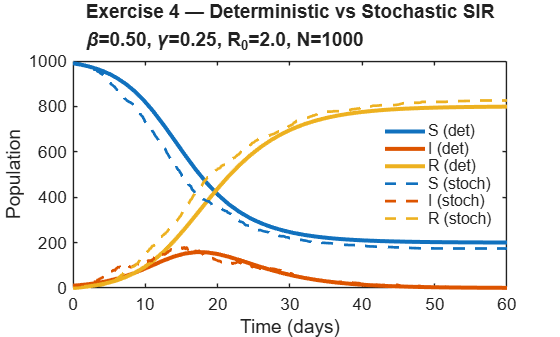


figure(9);

% deterministic ODE
[t_ode, y_ode] = ode45(@(t,y) sir_model(t,y,pars), [0 pars.tf], ...
    [pars.S0 pars.I0 0]/pars.N);
tmph = plot(t_ode, pars.N * y_ode);
set(tmph, 'linewidth', 3);
hold on;

% stochastic Gillespie simulation ---
[t_sto, y_sto] = stochsim_SIR([0 pars.tf], [pars.S0 pars.I0 0], pars);
tmphsim = plot(t_sto, y_sto, '--');
set(tmphsim, 'linewidth', 2);

% matching colors between deterministic (solid) and stochastic (dashed)
for i = 1:3
    set(tmphsim(i), 'color', get(tmph(i), 'color'));
end

xlabel('Time (days)'); ylabel('Population');
title(sprintf('Exercise 4 — Deterministic vs Stochastic SIR\n\\beta=%.2f, \\gamma=%.2f, R_0=%.1f, N=%d', ...
    pars.beta, pars.gamma, pars.R0, pars.N));
legend('S (det)','I (det)','R (det)', ...
    'S (stoch)','I (stoch)','R (stoch)', ...
    'Location','east');
legend('boxoff');
set(gca,'fontsize',13);
ylim([0 pars.N]);
hold off;

% function for SIR model 
function dydt = sir_model(t,y,pars)
% SIR Model — fractions (S+I+R=1)
S = y(1);
I = y(2);

dSdt = -pars.beta*S*I;
dIdt =  pars.beta*S*I - pars.gamma*I;
dRdt =  pars.gamma*I;

dydt = [dSdt; dIdt; dRdt];
end

% function for SI model 
function dydt = si_model(t,y,pars)
% SI Model — recovered individuals immediately become susceptible again
S = y(1);
I = y(2);

dSdt = -pars.beta*S*I + pars.gamma*I;
dIdt =  pars.beta*S*I - pars.gamma*I;

dydt = [dSdt; dIdt];
end

% stochastic SIR model 
function [t,y] = stochsim_SIR(trange,y0,pars)
% function [t,y] = stochsim_SIR(trange,y0,pars)
%
% Simulates an SIR model via the Gillespie algorithm
% from t0 to tf in trange given initial
% conditions in y0 = [S0 I0 R0] and parameters
% in pars. Returns time and values

t0 = trange(1);
tf = trange(2);
t(1)    = t0;
y(1,:)  = y0;
tcur    = t0;
ycur    = y0;
ind     = 1;

% Model
while (tcur < tf)

    % Check to see if there is an infection
    if (ycur(2) == 0)
        ind       = ind + 1;
        t(ind)    = tf;
        y(ind,:)  = ycur;
        break;
    end

    % rates
    infrate = pars.beta * ycur(1) * ycur(2) / pars.N;   % beta*S*I/N
    recrate = pars.gamma * ycur(2);                       % gamma*I
    totrate = infrate + recrate;
    dt   = -1/totrate * log(rand);
    tcur = tcur + dt;

    % conditions for whichever event
    if (rand < (infrate / totrate))   % INFECTION: S -> I
        ycur(1) = ycur(1) - 1;       %   S decreases by 1
        ycur(2) = ycur(2) + 1;       %   I increases by 1
    else                              % RECOVERY:  I -> R
        ycur(2) = ycur(2) - 1;       %   I decreases by 1
        ycur(3) = ycur(3) + 1;       %   R increases by 1
    end

    ind       = ind + 1;
    t(ind)    = tcur;
    y(ind,:)  = ycur;
end
end
